# Sensitivity analysis of rail lifetime of rail

## Input data

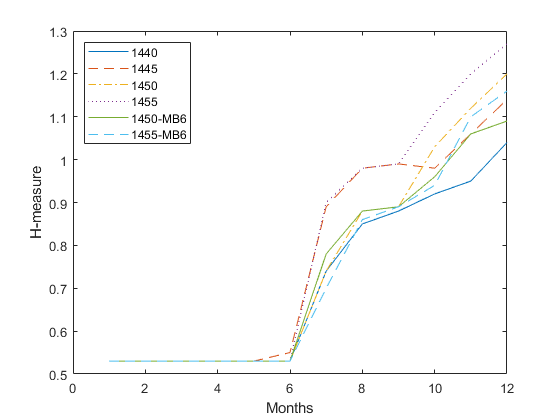

% read table with mechanical simulation results
filename = "mistra_results.xlsx";
sheet = "H_30t";
xlRange_MB5 = "B3:M6";
xlRange_MB6 = "B8:M9";
H_table_MB5 = xlsread(filename,sheet,xlRange_MB5);
H_table_MB6 = xlsread(filename,sheet,xlRange_MB6);

% gauge intervals (in mm)
gauge = [1440,1445,1450,1455];

% months
months = linspace(1,12,12);

% visualize the H_table
figure
plot(months, H_table_MB5(1,:), 'LineStyle',"-")
hold on
plot(months, H_table_MB5(2,:), 'LineStyle',"--")
plot(months, H_table_MB5(3,:), 'LineStyle',"-.")
plot(months, H_table_MB5(4,:), 'LineStyle',":")
plot(months, H_table_MB6(1,:), 'LineStyle',"-")
plot(months, H_table_MB6(2,:), 'LineStyle',"--")
legend('1440','1445','1450','1455','1450-MB6','1455-MB6','Location',"northwest")
xlabel('Months')
ylabel('H-measure')

## Data pre-processing ('linear' interpolation)

% interpolations of H table
H_table_interpol = zeros(size(gauge,2),12); % after 6 or 12 months
Xq = gauge;
Yq = [1,12];
for g_id=1:size(gauge,2)
    for m=1:12
        H_table_interpol(g_id,m) = interp2(Xq, Yq, H_table_MB5(:,Yq)', gauge(g_id), m,'linear');
    end
end

% visualize the interpolated H_tables
figure
plot(months, H_table_interpol(1,:), 'LineStyle',"-")
hold on
plot(months, H_table_interpol(2,:), 'LineStyle',"--")
plot(months, H_table_interpol(3,:), 'LineStyle',"-.")
plot(months, H_table_interpol(4,:), 'LineStyle',":")
legend('1440','1445','1450','1455','Location',"northwest")
xlabel('Months')
ylabel('H-measure')

## Sensitivity analysis (S1 - MB5, 2 grinding/year)

% average yearly gauge widening (in mm/year)
avg_yearly_gauge_widening = 0:0.1:2;

% maximum H (criterion for rail renewal)
H_max = 14;

% find the corresponding lifetime in years for scenario 1 (grinding each 6 months)
y_s1 = zeros(size(avg_yearly_gauge_widening));
for t=1:size(avg_yearly_gauge_widening,2)
    H_curr = 0;
    gauge_curr = 1440;
    for m=linspace(6,156,26) % over 13 years maximum
        % gauge increase after 6 months
        gauge_curr = gauge_curr+ avg_yearly_gauge_widening(t)/2;
        % corresponding increase in H measure
        H_curr = H_curr + interp2(Xq, Yq, H_table_MB5(:,Yq)', gauge_curr, 6,'linear');
        % stop if we need to renew the rail
        if(H_curr>=H_max || gauge_curr>1455)
            break;
        else
            y_s1(t) = y_s1(t) + 1/2;
        end
    end
    y_s1(t) = floor(y_s1(t));
    if(avg_yearly_gauge_widening(t)==1.5)
        H_curr
        gauge_curr
        y_s1(1,t)
    end
end

H_curr = 14.6968

gauge_curr = 1.4535e+03

ans = 8

## Sensitivity analysis (S2 - MB6, 1 grinding/year)

% gauge for MB6
Xq_MB6 = [1450 1455];

% find the corresponding lifetime in years for scenario 2 
y_s2 = zeros(size(avg_yearly_gauge_widening));
for t=1:size(avg_yearly_gauge_widening,2)
    nb_tamping = 0;
    H_curr = 0;
    gauge_curr = 1440;
    for m=linspace(12,156,13) % over 13 years maximum
        % gauge increase after X months
        gauge_curr = gauge_curr+ avg_yearly_gauge_widening(t);
        % corresponding increase in H measure (after 1450mm)
        if(gauge_curr<1450)
            H_curr = H_curr + H_table_MB6(1,12);
        elseif(gauge_curr>=1450 && gauge_curr<=1455)
            H_curr = H_curr + interp2(Xq_MB6, Yq, H_table_MB6(:,Yq)', gauge_curr, 12,'linear');
        elseif(gauge_curr>1455)
            nb_tamping = nb_tamping + 1;
            gauge_curr = 1440;
            H_curr = H_curr + interp2(Xq_MB6, Yq, H_table_MB6(:,Yq)', 1455, 12,'linear');
        end
        % stop if we need to renew the rail
        if(H_curr>=H_max)
            break;
        else
            y_s2(t) = y_s2(t) + 1;
        end
    end
    if(avg_yearly_gauge_widening(t)==1.5)
        H_curr
        gauge_curr
        y_s2(1,t)
        nb_tamping
    end
    y_s2(t) = floor(y_s2(t));
end

H_curr = 14.3940

gauge_curr = 1443

ans = 12

nb_tamping = 1

## Sensitivity analysis (S3 - MB5, 2 grinding/year & tamping when > 1450)

% find the corresponding lifetime in years for scenario 1 (grinding each 6 months)
y_s3 = zeros(size(avg_yearly_gauge_widening));
for t=1:size(avg_yearly_gauge_widening,2)
    nb_tamping = 0;
    H_curr = 0;
    gauge_curr = 1440;
    for m=linspace(6,156,26) % over 13 years maximum
        % gauge increase after 6 months
        gauge_curr = gauge_curr + avg_yearly_gauge_widening(t)/2;
        % corresponding increase in H measure
        H_curr = H_curr + interp2(Xq, Yq, H_table_MB5(:,Yq)', gauge_curr, 6,'spline');
        % stop if we need to renew the rail
        if(gauge_curr>=1450)
            nb_tamping = nb_tamping + 1;
            gauge_curr = 1440;
        end
        if(H_curr>=H_max)
            break;
        else
            y_s3(t) = y_s3(t) + 1/2;
        end
    end
    if(avg_yearly_gauge_widening(t)==1.5)
        H_curr
        gauge_curr
        y_s3(1,t)
        nb_tamping
    end
    y_s3(t) = floor(y_s3(t));
end

H_curr = 14.4136

gauge_curr = 1443

ans = 8.5000

nb_tamping = 1

## Plot results

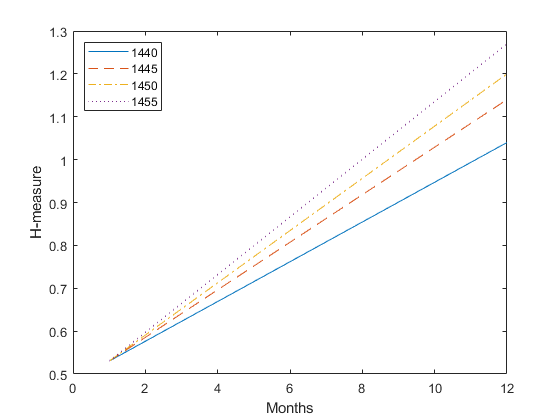

hold off

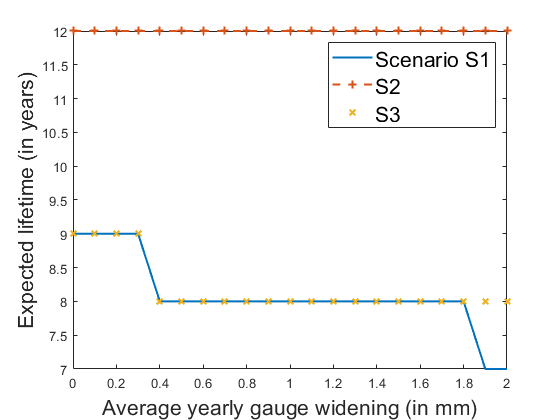

figure
plot(avg_yearly_gauge_widening,y_s1','LineWidth',1.5, 'LineStyle',"-")
hold on
plot(avg_yearly_gauge_widening,y_s2',"+",'LineWidth',1.5, 'LineStyle',"--")
plot(avg_yearly_gauge_widening,y_s3',"x",'LineWidth',1.5)%, 'LineStyle',":")
legend('Scenario S1', 'S2', 'S3', 'FontSize', 16)
xlabel('Average yearly gauge widening (in mm)','FontSize', 16)
ylabel('Expected lifetime (in years)', 'FontSize', 16)